# Quiz 3: Cleaning Your Data

flights = importFlightsData("flightsJan.csv");

miss = ismissing(flights)

miss = 469968×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0


missVar = sum(miss)

missVar =            0        2782           0           0           0           0       11657       11657       11876       12955       12271           0       12271       12955           0       12955           0           0      457986           0


nMissVar = nnz(missVar)

nMissVar = 10

flights.SCHEDULED_DEPARTURE_HOUR = dateshift(flights.SCHEDULED_DEPARTURE_TIME,"start","hour");
flightsNotArriving = groupsummary(flights,"SCHEDULED_DEPARTURE_HOUR","sum",["DIVERTED" , "CANCELLED"]);
flightsNotArriving.Properties.VariableNames = [ "Scheduled_Departure_Hour" "Total_Flights" "Diverted_Flights" "Cancelled_Flights"]

flightsNotArriving = 725×4 table
    Scheduled_Departure_Hour    Total_Flights    Diverted_Flights    Cancelled_Flights
    ________________________    _____________    ________________    _________________

      01-Jan-2015 00:00:00            21                0                    0        
      01-Jan-2015 01:00:00            21                0                    1        
      01-Jan-2015 02:00:00             8                0                    1        
      01-Jan-2015 03:00:00             2                0                    0        
      01-Jan-2015 04:00:00             4                0                    0        
      01-Jan-2015 05:00:00           116                0                    7        
      01-Jan-2015 06:00:00           658                1                   64        
      01-Jan-2015 07:00:00           722       


[cancelled, outlierIdx] = rmoutliers(flightsNotArriving.Cancelled_Flights,'quartiles');
nOutliers = nnz(outlierIdx)

nOutliers = 59

flightsNotArriving = flightsNotArriving(~outlierIdx,:);

% Smooth input data
smoothedData = smoothdata(flightsNotArriving.Diverted_Flights,'movmean',days(7),...
    'SamplePoints',flightsNotArriving.Scheduled_Departure_Hour);

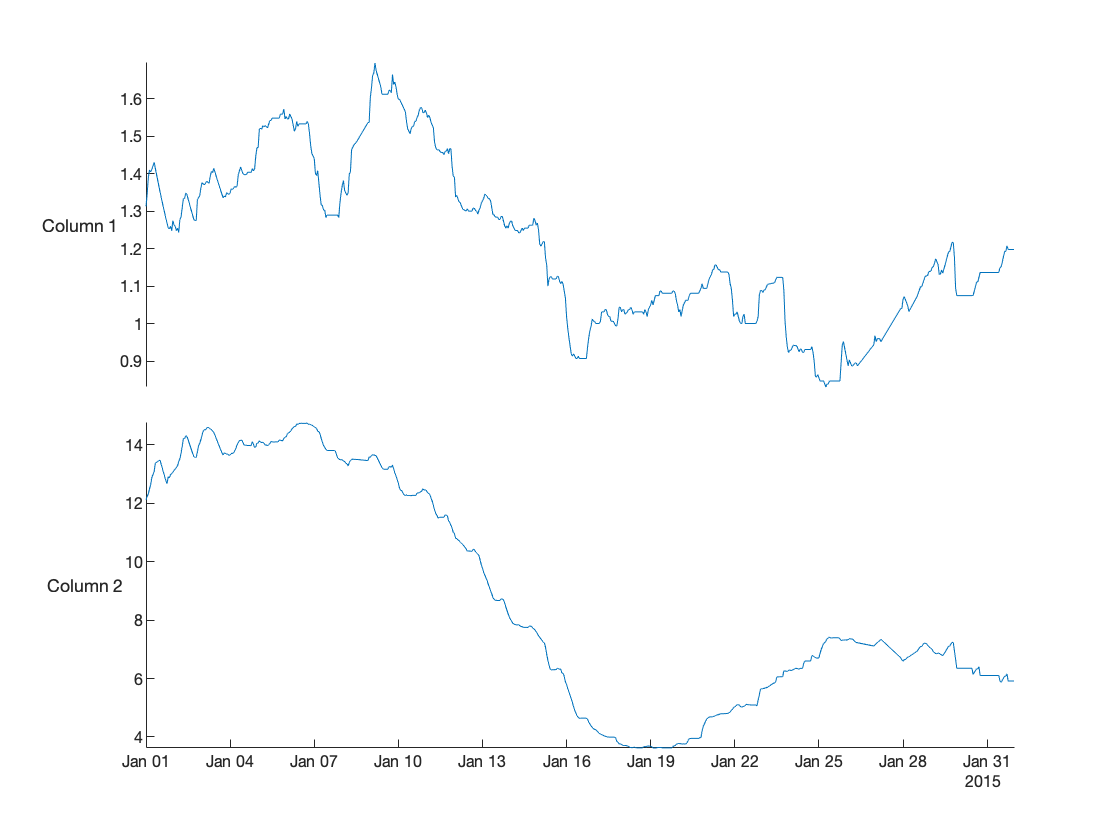

% Smooth input data
smoothedData2 = smoothdata(flightsNotArriving.Cancelled_Flights,...
    'movmean',days(7),...
    'SamplePoints',flightsNotArriving.Scheduled_Departure_Hour);
stackedplot(flightsNotArriving.Scheduled_Departure_Hour,[smoothedData,smoothedData2])


corrSmoothed = corr(smoothedData,smoothedData2)

corrSmoothed = 0.8334

normalize()